# Transformations Exercises Solutions

### Exercise 10

A = [1 , 2 , -1 ; 
     3 , 0 , 1 ;
     2 , -1 , 3 ];

u = [2 ; 5 ; 1];
sym(A * u)

$$ans = \left(\begin{array}{c} 11\\ 7\\ 2 \end{array}\right)$$

### Exercise 11

u1 = [1 ; -1 ; 0];
u2 = [0 ; 1 ; 2];
u3 = [-1 ; 1 ; 1];
Tu1 = [1 ; -2 ; -4];
Tu2 = [6 ; 5 ; 10];
Tu3 = [2 ; 4 ; 7];

A = sym([Tu1, Tu2, Tu3] * inv([u1, u2, u3]))

$$A = \left(\begin{array}{ccc} 1 & 0 & 3\\ -1 & 1 & 2\\ 0 & 4 & 3 \end{array}\right)$$

### Exercise 12

(a)

L = 2;
c = [3, 2];

x1 = c(1) - L/2;
x2 = c(1) + L/2;
x3 = c(1);
syms y1
h = sqrt(L^2 - (L/2)^2);
y1 = solve(c(2) == (y1 + y1 + y1 + h)/3);
y2 = y1;
y3 = y1 + h;

v1 = [x1 ; y1]

$$v1 = \left(\begin{array}{c} 2\\ 2-\frac{\sqrt{3}}{3} \end{array}\right)$$

v2 = [x2 ; y2]

$$v2 = \left(\begin{array}{c} 4\\ 2-\frac{\sqrt{3}}{3} \end{array}\right)$$

v3 = [x3 ; y3]

$$v3 = \left(\begin{array}{c} 3\\ \frac{2\,\sqrt{3}}{3}+2 \end{array}\right)$$

(c)

clear

% Define vertex array
P = [ 2, 4, 3 ;
      2 - sqrt(3)/3, 2 - sqrt(3)/3, 2 + 2 * sqrt(3)/3 ;
      1, 1, 1 ];

% Define translation matrix
T = @(t) [1, 0, t(1) ; 
          0, 1, t(2) ;
          0, 0, 1 ];

% Apply translation
t = [3 ; 1];
P1 = T(t) * P

P1 =     5.0000    7.0000    6.0000
    2.4226    2.4226    4.1547
    1.0000    1.0000    1.0000


(d)

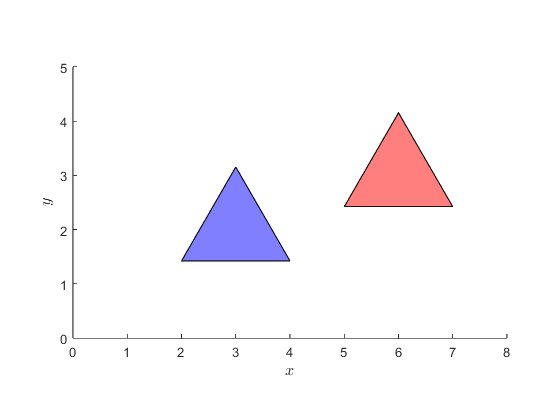

figure
patch(P(1,:), P(2,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(2,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 8, 0, 5])
xlabel('$x$', FontSize=12, Interpreter='latex')
ylabel('$y$', FontSize=12, Interpreter='latex')
exportgraphics(gcf,'../images/exercise_12d.png', 'Resolution', 300)

### Exercise 13

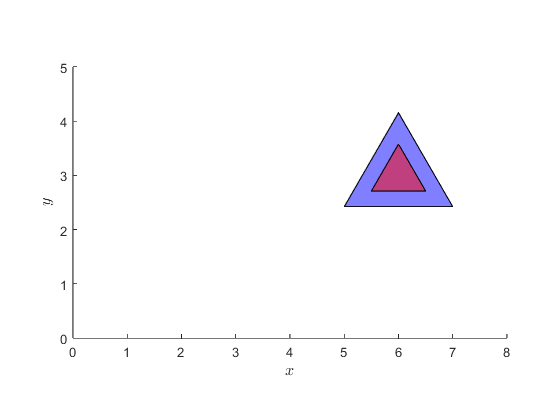

% Calculate centre of the triangle
c = mean(P1, 2);

% Define scaling matrix
S = @(s) [ s(1), 0, 0 ;
           0, s(2), 0 ;
           0, 0, 1 ];

% Apply transformations (remembering to translate to and from origin)
s = [0.5 ; 0.5];
P2 = T(c) * S(s) * T(-c) * P1;

% Plot pre and post scaled triangle
figure
patch(P1(1,:), P1(2,:), 'b', FaceAlpha=0.5)
patch(P2(1,:), P2(2,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 8, 0, 5])
xlabel('$x$', FontSize=12, Interpreter='latex')
ylabel('$y$', FontSize=12, Interpreter='latex')
exportgraphics(gcf,'../images/exercise_13.png', 'Resolution', 300)

### Exercise 14

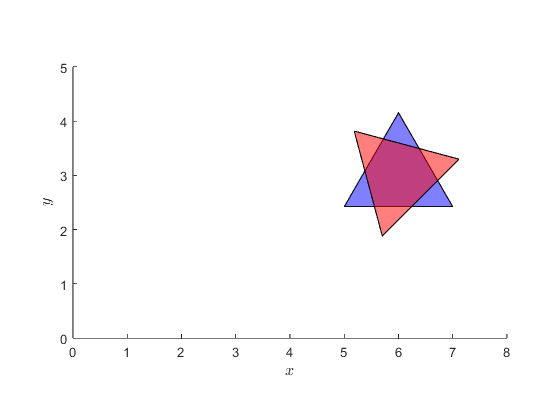

% Calculate centre of the triangle
c = mean(P1, 2);

% Define rotation matrix
R = @(th) [ cos(th), -sin(th), 0 ;
            sin(th), cos(th), 0 ;
            0, 0, 1 ];

% Apply transformations (remembering to translate to and from origin)
theta = pi / 4;
P3 = T(c) * R(theta) * T(-c) * P1;

% Plot pre and post scaled triangle
figure
patch(P1(1,:), P1(2,:), 'b', FaceAlpha=0.5)
patch(P3(1,:), P3(2,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 8, 0, 5])
xlabel('$x$', FontSize=12, Interpreter='latex')
ylabel('$y$', FontSize=12, Interpreter='latex')
exportgraphics(gcf,'../images/exercise_14.png', 'Resolution', 300)

### Exercise 15

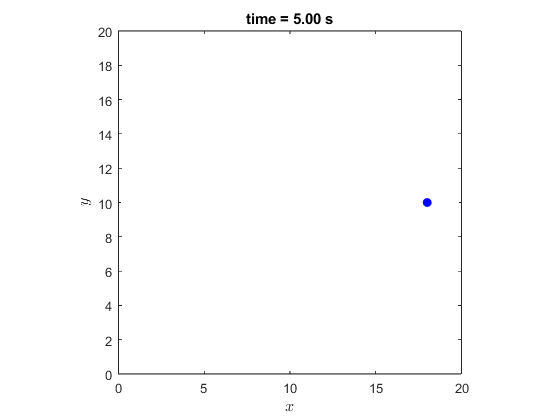

% Define arc parameters
c = [10 ; 10];
r = 8;

% Loop through animation frames
fps = 60;
for t = 0 : 1/fps : 5

    % Calculate point position
    phi = t * 2 * pi;
    p = c + r * [cos(phi) ; sin(phi)];

    % Plot square centre 
    clf
    plot(p(1), p(2), 'bo', MarkerFaceColor='b')
    axis equal
    axis([0, 20, 0, 20])
    title(sprintf('time = %1.2f s', t))
    xlabel('$x$', FontSize=12, Interpreter='latex')
    ylabel('$y$', FontSize=12, Interpreter='latex')
    box on
    drawnow
end

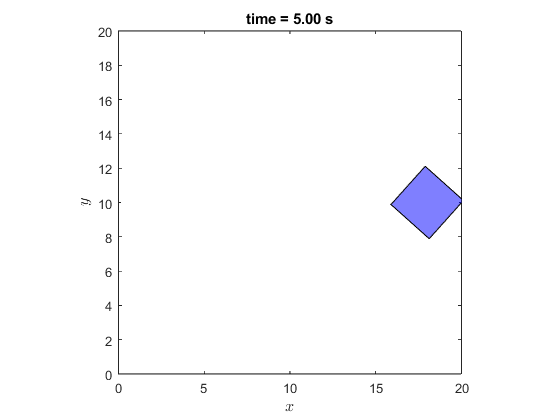

clear

% Define arc parameters
c = [10 ; 10];
r = 8;

% Define square centred at the origin
P = [ -0.5,  0.5, 0.5, -0.5 ;
      -0.5, -0.5, 0.5,  0.5 ;
       1,    1,   1,    1 ];

% Define transformation matrices
T = @(t) [1, 0, t(1) ; 
          0, 1, t(2) ;
          0, 0, 1 ];
S = @(s) [ s(1), 0, 0 ;
           0, s(2), 0 ;
           0, 0, 1 ];
R = @(th) [ cos(th), -sin(th), 0 ;
            sin(th), cos(th), 0 ;
            0, 0, 1 ];

fps = 60;
for t = 0 : 1/fps : 5

    % Calculate square centre position
    phi = t * 2 * pi;
    p = c + r * [cos(phi) ; sin(phi)];

    % Transform square
    P1 = T(p) * R(-8*t) * S([2+cos(5*t), 2+cos(5*t)]) * P;
    
    % Plot square
    clf
    patch(P1(1,:), P1(2,:), 'b', FaceAlpha=0.5)
    axis equal
    axis([0, 20, 0, 20])
    title(sprintf('time = %1.2f s', t))
    xlabel('$x$', FontSize=12, Interpreter='latex')
    ylabel('$y$', FontSize=12, Interpreter='latex')
    box on
    drawnow
    exportgraphics(gcf,'exercise_15.gif','Append',true);
end
exportgraphics(gcf,'../images/exercise_15.png', 'Resolution', 300)

### Exercise 16

clear

p = [2 ; -4 ; -3];
d = [-2 ; 3 ; 4];

T = @(t) [ 1, 0, 0, t(1) ;
           0, 1, 0, t(2) ;
           0, 0, 1, t(3) ;
           0, 0, 0, 1 ];

d1 = sym(sqrt(d(1)^2 + d(2)^2));
c = abs(d(1)) / d1;
s = abs(d(2)) / d1;
Rz = [ c, -s, 0, 0 ;
       s, c, 0, 0 ;
       0,  0,  1, 0 ;
       0,  0,  0, 1 ];
Rz * [d ; 1]

$$ans = \left(\begin{array}{c} -\sqrt{13}\\ 0\\ 4\\ 1 \end{array}\right)$$

magd = sym(norm(d))

$$magd = \sqrt{29}$$

c = abs(d(3)) / magd;
s = d1 / magd;
Ry = [ c, 0, s, 0 ;
       0, 1, 0, 0 ;
      -s, 0, c, 0 ;
       0, 0, 0, 1 ]

$$Ry = \left(\begin{array}{cccc} \frac{4\,\sqrt{29}}{29} & 0 & \frac{\sqrt{13}\,\sqrt{29}}{29} & 0\\ 0 & 1 & 0 & 0\\ -\frac{\sqrt{13}\,\sqrt{29}}{29} & 0 & \frac{4\,\sqrt{29}}{29} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ry * Rz * [d ; 1]

$$ans = \left(\begin{array}{c} 0\\ 0\\ \sqrt{29}\\ 1 \end{array}\right)$$